# KF Function Demo Fixed Compare

% system clear

% clc; clearvars -except i_Q  i_R z x k_cur_pos;
clc; clear all;



$$$$\textbf {KalMan Filter}$$
$$$$
$$Predict\ step:$$
$$ \quad{ \hat{\mathbf{x}}_{k\mid k-1} = \mathbf{F}_k \hat\mathbf{x}_{k-1\mid k-1} + \mathbf{B}_k \mathbf{u}_{k}} $$
$$ \quad{ {\mathbf{P}}_{k\mid k-1} = \mathbf{F}_k \mathbf{P}_{k-1 \mid k-1} \mathbf{F}_k^\textsf{T} + \mathbf{Q}_{k}} $$
$$Update\ step:$$
$$ \quad{ \mathbf{K}_k = {\mathbf{P}}_{k\mid k-1}\mathbf{H}_k^\textsf{T} {\left(\mathbf{H}_k {\mathbf{P}}_{k\mid k-1} \mathbf{H}_k^\textsf{T} + \mathbf{R}_k\right)}^{-1}} $$
$$ \quad{ \hat{\mathbf{x}}_{k\mid k} = \hat{\mathbf{x}}_{k\mid k-1} + \mathbf{K}_k{\left(\mathbf{z}_k - \mathbf{H}_k\hat{\mathbf{x}}_{k\mid k-1}\right)} $$
$$ \quad{ \mathbf{P}_{k|k} = \left(\mathbf{I} - \mathbf{K}_k \mathbf{H}_k\right) {\mathbf{P}}_{k|k-1}} $$$$


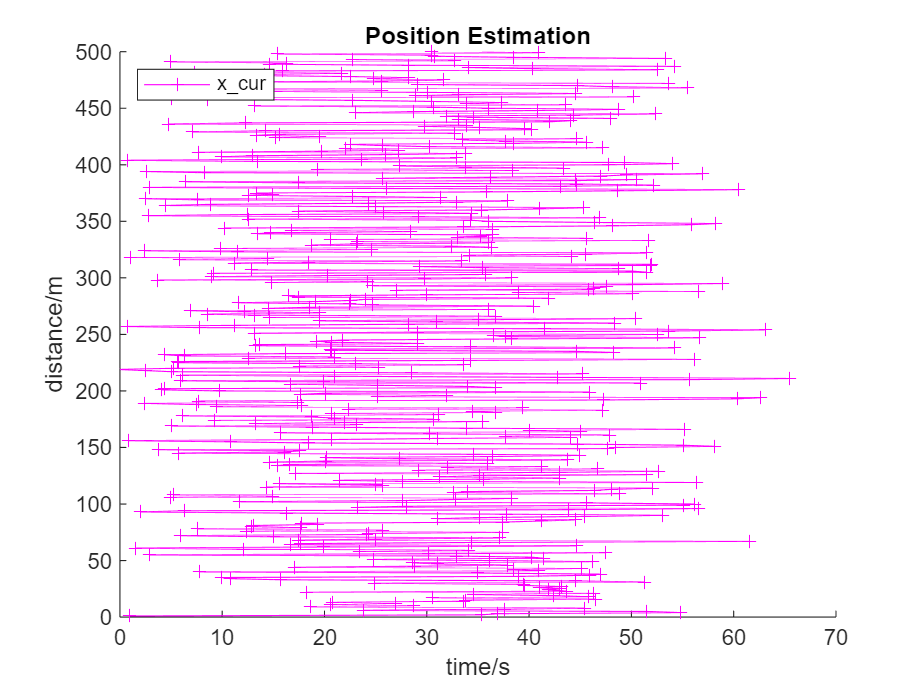


% step 0: config parameters
load("KF_Calc_SUnit_Fixed_Src.m", '-mat');

[~, ~, END_T] = size(x);
DELTA_T = 1;

LEN = length(1:DELTA_T:END_T);

% step 1: set init
k_cur = zeros(2,1,LEN);
x_cur = zeros(2,1,LEN);
p_cur = zeros(2,2,LEN);

% step 2: predict
% step 3: update
for idx_i = 1:LEN
    
    [o_x_cur, o_p_cur]= KF_Calc_SUnit_Fixed_S3(i_Q(1,idx_i), i_R(1,idx_i), i_z(:,idx_i));

    x_cur(:,:,idx_i) = o_x_cur;
    p_cur(:,:,idx_i) = o_p_cur;
end

% step 4: disp
hold off; hold on;

axis([0 LEN 0 LEN]);
title('Position Estimation');
xlabel('time/s');
ylabel('distance/m');

y_plot(:) = (1:LEN);

x_cur_plot(:) = x_cur(1,1,:);
plot(x_cur_plot, y_plot, 'm-+');

xlim([0 70]);
ylim([0 500]);

legend('x\_cur', 'Location','northwest');